## Temperature dependent adjustment of $V_c$ and $V_o$

### Bernacchi temperature functions

Currently the e-Photosynthesis model sets PrV111 = PsV1 * 0.24, according to the known value for tobacco at 25°C (Whitney et al., 1999).

However, this ratio varies across different crop species and temperatures.

Seeing as there is no existing temperature functions for rice, we will use the equations by Bernacchi (2001) and values from Makino (1988) to compare the temperature responses of the parameters.

Specify constants:

T25 = 25 + 273.15;                 % Reference temperature in K 
Tp = 28.9310407291759 + 273.15;    % Average measurement temperature in K
R = 0.008314;                      % Ideal gas constant in kJ K-1 mol-1
c_Vc = 26.35;                      % Scaling constant, Vcmax             (N. tabacum L. cv. W38, Bernacchi et al 2001)
dHa_Vc = 65.33;                    % Activation energy, Vcmax, kJ mol -1 (N. tabacum L. cv. W38, Bernacchi et al 2001)
c_Vo = 22.98;                      % Scaling constant, Vomax             (N. tabacum L. cv. W38, Bernacchi et al 2001)
dHa_Vo = 60.11;                    % Activation energy, Vomax, kJ mol -1 (N. tabacum L. cv. W38, Bernacchi et al 2001)

Use the Arrhenius equation $\textrm{Parameter}=\exp \;\left(c-\frac{\Delta H_a }{RT_K }\right)\;$to calculate the $\frac{V_o }{V_c }$ ratio at 25°C for *N.tabacum* (c and dHa from Bernacchi et al., 2001):

Bernacchi_Vc_25 = exp(c_Vc - dHa_Vc / (R * T25)); 
Bernacchi_Vo_25 = exp(c_Vo - dHa_Vo / (R * T25));
Bernacchi_PrPs_ratio_25 = Bernacchi_Vo_25/Bernacchi_Vc_25;

Specify a range of temperatures for calculating Vo/Vc ratios:

Temp_Range(:,1) = (10:1:40)';                                 % Range of temperatures in C
Vo_Vc_matrix = deal(zeros(length(Temp_Range),5));             % Output matrix

Loop the Arrhenius equation to calculate values over the range of temperatures:

for i = 1:length(Temp_Range)
Vo_Vc_matrix(i,1) = Temp_Range(i,1);                                          % Range of temperatures in C
Vo_Vc_matrix(i,2) = Temp_Range(i,1)+273.15;                                   % Range of temperatures in K
Vo_Vc_matrix(i,3) = exp(c_Vc - dHa_Vc / (R * Vo_Vc_matrix(i,2)));             % Vc values
Vo_Vc_matrix(i,4) = exp(c_Vo - dHa_Vo / (R * Vo_Vc_matrix(i,2)));             % Vo values
Vo_Vc_matrix(i,5) = Vo_Vc_matrix(i,4)/Vo_Vc_matrix(i,3);                      % Vo/Vc ratios
end

Plot Vo/Vc data:

figure;
Vo_Vc_plot = plot(Temp_Range(:,1),Vo_Vc_matrix(:,5))

Vo_Vc_plot =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40]
              YData: [0.3158 0.3134 0.3109 0.3086 0.3062 0.3039 0.3016 0.2994 0.2971 0.2950 0.2928 0.2907 0.2886 0.2865 0.2845 0.2825 0.2805 0.2785 0.2766 0.2747 0.2728 0.2710 0.2692 0.2674 0.2656 0.2638 0.2621 0.2604 0.2587 0.2570 0.2554]

  Show all properties


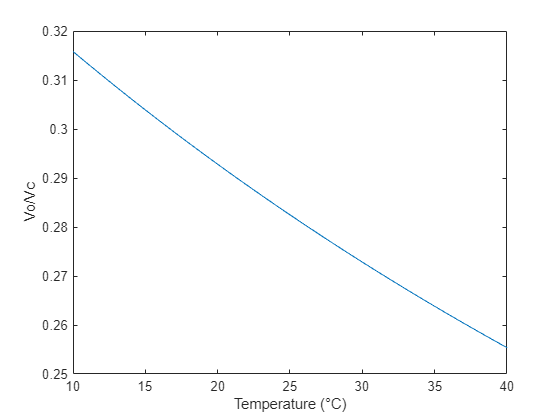

xlabel('Temperature (°C)')
ylabel('Vo/Vc')

set(gcf, 'PaperOrientation', 'landscape');
print(gcf,fullfile('Outputs/rice_params/graphs',"Temp_vs_Vo_Vc"),'-djpeg');

Plot Vc and Vo for comparison:

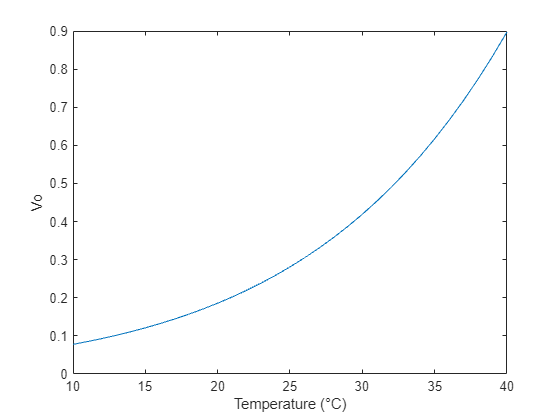

figure;
Vo_plot = plot(Temp_Range(:,1),Vo_Vc_matrix(:,4));
xlabel('Temperature (°C)');
ylabel('Vo');

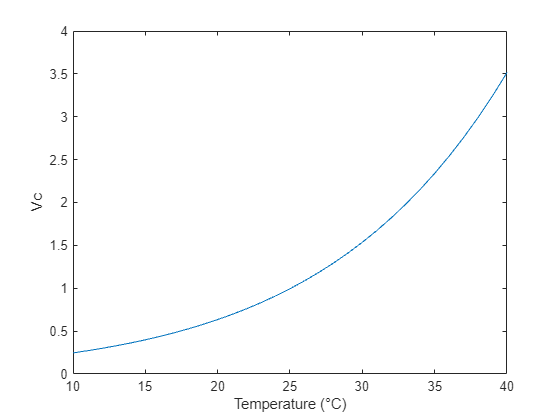

set(gcf, 'PaperOrientation', 'landscape');
print(gcf,fullfile('Outputs/rice_params/graphs',"Temp_vs_Vo"),'-djpeg');
figure;
Vc_plot = plot(Temp_Range(:,1),Vo_Vc_matrix(:,3));
xlabel('Temperature (°C)');
ylabel('Vc');

set(gcf, 'PaperOrientation', 'landscape');
print(gcf,fullfile('Outputs/rice_params/graphs',"Temp_vs_Vc"),'-djpeg');

Calculate $V_c$ and $\frac{V_o }{V_c }$ ratio for Bernacchi at measurement temperature $T_p$:

Bernacchi_Vc_Tp = exp(c_Vc - dHa_Vc / (R * Tp)); 
Bernacchi_Vo_Tp = exp(c_Vo - dHa_Vo / (R * Tp)); 
Bernacchi_PrPs_ratio_Tp = Bernacchi_Vo_Tp/Bernacchi_Vc_Tp;

Work out the $\frac{V_o }{V_c }$ ratio for rice at 25°C using data in Makino et al (1988):

Makino_Vc_25 = 1.77; % RuBP carboxylase activity at pH 8.15 and 25°C from rice leaves (umol(mg enzyme)-1 min-1 (Vmax)
Makino_Vo_25 = 0.58; % RuBP oxygenase activity at pH 8.15 and 25°C from rice leaves (umol(mg enzyme)-1 min-1 (Vmax)
Makino_PrPs_ratio_25 = Makino_Vo_25/Makino_Vc_25; % Check this matches the value in von Caemmerer (2000)

### Adjusting the value $V_{\textrm{cmax}}$ at 25°C to measurement temperature $T_p$

We can use one of two approaches to calculate the Makino value of $\frac{V_o }{V_c }$ at Tp:

- Use the ratios of Makino and Bernacchi at 25°C and multiply by Bernacchi parameter estimate at a given temperature

- Fit an Arrhenius equation to a non-linear model to find the Bernacchi temperature response of $\frac{V_o }{V_c }$ (plotted above)

Use linear scaling of Makino to Bernacchi ratios:

Makino_PrPs_ratio_Tp = Makino_PrPs_ratio_25*Bernacchi_PrPs_ratio_Tp/Bernacchi_PrPs_ratio_25

Makino_PrPs_ratio_Tp = 0.3188

%OR 
%Makino_PrPs_ratio_Tp = Makino_PrPs_ratio_25/Bernacchi_PrPs_ratio_25*Bernacchi_PrPs_ratio_Tp

### Non-linear fits for $\frac{V_o }{V_c }$

#### Define predictor (T) and response (y) variables:

T = Vo_Vc_matrix(:,2); % Temp in K
y = Vo_Vc_matrix(:,5); % Vo/Vc ratio

So far, we have defined the Arrhenius equation as:


$$\textrm{Parameter}=\exp \;\left(c-\frac{\Delta H_a }{RT_K }\right)$$


c is meant to scale the amplitude of the function whereas dHa represents the temperature dependence relationship.

Using the term c−dHa combined these two effects into one, making them harder to interpret individually.

Without c, the model assumes that dHa depends solely on temperature and ignores other potential variations.

This means the equation can also be rewritten as:


$$y=c\cdot \exp \left(-\frac{\Delta H_a }{RT_K }\right)$$


to ensure that the exponent has a negative sign - previously exp(c-dHa/R*T) was causing errors since the exponent was positive.

Define an exponential model with non-linear parameters using this form of the Arrhenius equation.

Start by creating a fit type for a custom nonlinear model, designating R as the problem-dependent parameter and T as the independent variable. 

arrhenius_model = fittype('c * exp(-dHa ./ (R * T))', ...
                'independent', 'T', ...
                'coefficients', {'c', 'dHa'}, ...
                'problem', 'R');

Fit the model using the fit function and passing in the custom model structure with initial guesses for c and dHa in StartPoint and R as a problem-dependent constant:

fittedModel = fit(T(:), y(:), arrhenius_model, 'StartPoint', [0, 2], 'problem', R)

fittedModel =      General model:
     fittedModel(T) = c * exp(-dHa ./ (R * T))
     Coefficients (with 95% confidence bounds):
       c =     0.03439  (0.03439, 0.03439)
       dHa =       -5.22  (-5.22, -5.22)
     Problem parameters:
       R =    0.008314

Plot the non-linear fit of the model to the data:

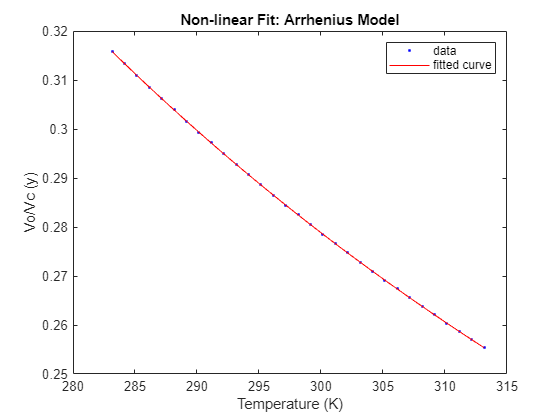

figure;
nls_plot = plot(fittedModel, T, y);
xlabel('Temperature (K)');
ylabel('Vo/Vc (y)');
title('Non-linear Fit: Arrhenius Model');

set(gcf, 'PaperOrientation', 'landscape');
print(gcf,fullfile('Outputs/rice_params/graphs',"Temp_vs_VoVc_nls"),'-djpeg');

Calculate the residuals:

% Specify predicted values from the model
y_fit = fittedModel(T); 

% Calculate residuals by subtracting from the observed y values
residuals = y - y_fit;  % Observed - Predicted

Plot residuals against T:

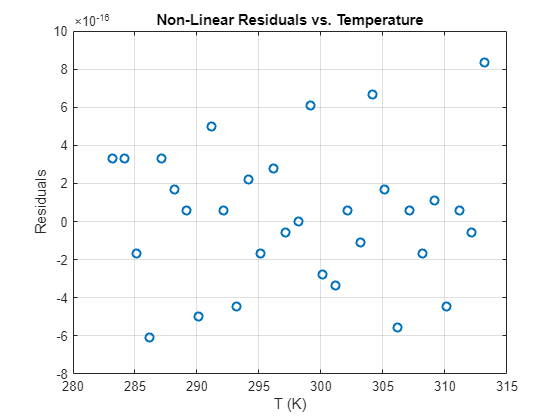

figure;
nls_residualsT_plot = plot(T, residuals, 'o', 'LineWidth', 1.5);
xlabel('T (K)');
ylabel('Residuals');
title('Non-Linear Residuals vs. Temperature');
grid on;

Plot residuals against fitted values:

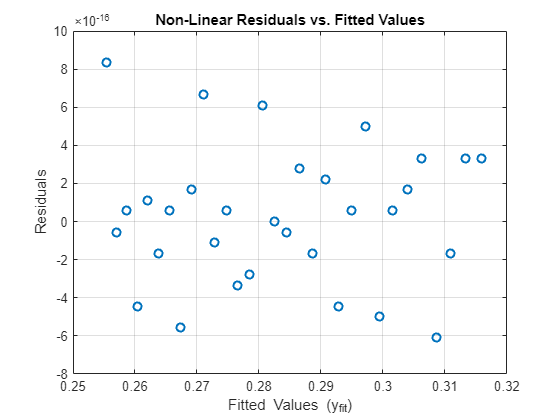

figure;
nls_residuals_plot = plot(y_fit, residuals, 'o', 'LineWidth', 1.5);
xlabel('Fitted Values (y_{fit})');
ylabel('Residuals');
title('Non-Linear Residuals vs. Fitted Values');
grid on;

Random scatter around zero indicates we have a good fit of model to data.

The values of the residuals are also very small (<$10\times {10}^{-16}$), indicating the model accounts for all variations in the data and there are no unexplained residuals left.

Calculate R-squared:

SST = sum((y - mean(y)).^2)     % Total sum of squares

SST = 0.0100

SSR = sum(residuals.^2)         % Residual sum of squares

SSR = 3.9166e-30

R_squared = 1 - (SSR / SST)

R_squared = 1

Check confidence intervals:

conf_int = confint(fittedModel)

conf_int =     0.0344   -5.2200
    0.0344   -5.2200


The R-squared is exactly 1, which indicates all the data points lie on the fitted curve perfectly.

Alternative: use nlinfit from Statistics and Machine Learning Toolbox:

Define the model function where c is b(1) and dHa is b(2):

modelfun =  @(params, T) params(1) * exp(-params(2) ./ (R * T));

Pre-assign initial guesses for c and dHa:

initial_guesses = [0,2];

Fit using nlinfit:

nlin_fit = nlinfit(T,y,modelfun,initial_guesses)

nlin_fit =     0.0344   -5.2200


c_nlin = nlin_fit(1)

c_nlin = 0.0344

dHa_nlin = nlin_fit(2)

dHa_nlin = -5.2200

Obtain predictions from fitted model:

y_fit_nlin = modelfun(nlin_fit, T);

Plot non-linear fit from nlinfit on top of observed data:

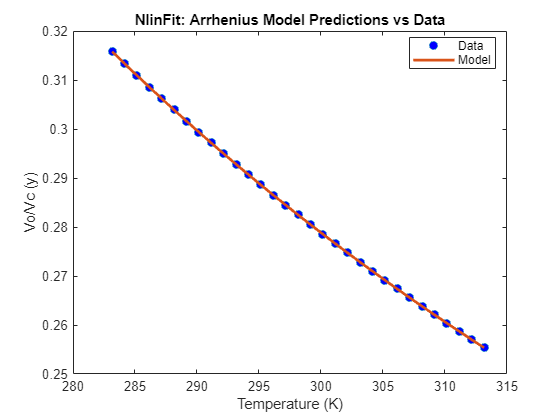

% Plot observed data
figure;
nlin_plot = plot(T, y, 'o', 'MarkerFaceColor', 'blue', 'DisplayName', 'Data');
hold on;

% Plot model predictions (at observed T values)
plot(T, y_fit_nlin, '-', 'LineWidth', 2, 'DisplayName', 'Model');
xlabel('Temperature (K)');
ylabel('Vo/Vc (y)');
legend('Location', 'best');
title('NlinFit: Arrhenius Model Predictions vs Data');
set(gcf, 'PaperOrientation', 'landscape');
print(gcf,fullfile('Outputs/rice_params/graphs',"Temp_vs_VoVc_nlinfit"),'-djpeg');

Fit a linear model for compare with model fitted using fit:

linear_model = fit(T(:), y(:), 'poly1');
y_linear_fit = linear_model(T);
disp(linear_model)

     Linear model Poly1:
     linear_model(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =   -0.002008  (-0.00205, -0.001966)
       p2 =      0.8822  (0.8696, 0.8947)


Plot the linear model:

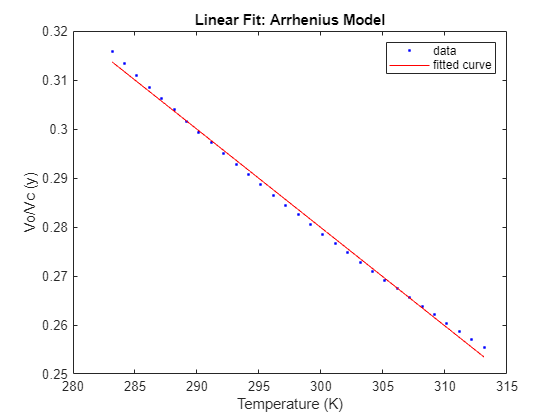

figure;
lin_plot = plot(linear_model, T, y);
xlabel('Temperature (K)');
ylabel('Vo/Vc (y)');
title('Linear Fit: Arrhenius Model');

Compare R-squared values between linear and non linear:

SSR_linear = sum((y - y_linear_fit).^2)

SSR_linear = 3.0392e-05

R2_linear = 1 - (SSR_linear / SST)

R2_linear = 0.9970

R2_complex = 1 - (SSR / SST)

R2_complex = 1

The simpler linear model performs almost as well as the more complex non-linear model, but does not predict correctly across the entire range.

The points being fit are predictions from fitted models, so they have no associated measurement error and the non-linear is NOT overfitting.

*However, if we were fitting actual data and generalising to values outside this dataset, it may be advisable to simplify the model.

Save the nonlinear fit derived coefficients for c and dHa:

coeffs_VoVc = coeffvalues(fittedModel);
c_VoVc = coeffs_VoVc(1);
dHa_VoVc = coeffs_VoVc(2);

Work out conversion ratio between Bernacchi and Makino Vo/Vc ratios at 25:

conv_ratio = Makino_PrPs_ratio_25/Bernacchi_PrPs_ratio_25;

Predict Vo/Vc value at Tp using the estimated parameters:

Bernacchi_PrPs_ratio_Tp2 = (c_VoVc * exp(-dHa_VoVc ./ (R * Tp)))

Bernacchi_PrPs_ratio_Tp2 = 0.2748

Correcting for the conversion:

Makino_PrPs_ratio_Tp2 = Bernacchi_PrPs_ratio_Tp2*conv_ratio

Makino_PrPs_ratio_Tp2 = 0.3188

Compare the two values obtained for Makino ratios at Tp:

isequal(Makino_PrPs_ratio_Tp,Makino_PrPs_ratio_Tp2)

ans = logical
   0


Although isequal returns 0,  this value is essentially the same (upto 14 dp) as the one calculated using Method 1) multiplying the ratios of Makino and Bernacchi at 25°C by the Bernacchi parameter estimate at Tp.

We can also compare the values by re-scaling the $\frac{V_o }{V_c }$ ratio from Bernacchi so it has a value of 1 at 25°C and then fitting the Arrhenius function using these values.

Divide all  $\frac{V_o }{V_c }$ values calculated at different temperatures by the value at 25°C:

normalized_ratios = y/Bernacchi_PrPs_ratio_25;

Obtain Arrhenius constants using the rescaled values as y:

fittednormModel = fit(T(:), normalized_ratios(:), arrhenius_model, 'StartPoint', [0, 2], 'problem', R)

fittednormModel =      General model:
     fittednormModel(T) = c * exp(-dHa ./ (R * T))
     Coefficients (with 95% confidence bounds):
       c =      0.1217  (0.1217, 0.1217)
       dHa =       -5.22  (-5.22, -5.22)
     Problem parameters:
       R =    0.008314

coeffs_normModel = coeffvalues(fittednormModel);
c_norm = coeffs_normModel(1)

c_norm = 0.1217

dHa_norm = coeffs_normModel(2)

dHa_norm = -5.2200

Predict the Bernacchi ratio at Tp using parameters obtained from non-linear fit of normalised values:

Bernacchi_PrPs_ratio_Tp3 = (c_norm * exp(-dHa_norm ./ (R * Tp)))

Bernacchi_PrPs_ratio_Tp3 = 0.9730

This ratio is different from the other two ratios since we re-scaled the y values and obtained a new $c$ parameter value.

Multiply the Bernacchi ratio at Tp by the Makino ratio at 25°C:

Makino_PrPs_ratio_Tp3 = Makino_PrPs_ratio_25*Bernacchi_PrPs_ratio_Tp3

Makino_PrPs_ratio_Tp3 = 0.3188